% Image data
imdata1 = imread('book.jpg');
image1 = rgb2gray(imdata1);
image1 = im2double(image1);
  
imdata2 = imread('pumpkin.jpg');
image2 = rgb2gray(imdata2);
image2 = im2double(image2);

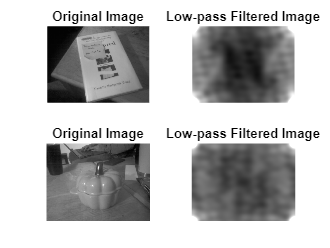

% Apply low pass filter
[~,lowpass1] = low_pass_filter(image1,10);
[~,lowpass2] = low_pass_filter(image2,10);

figure;
subplot(2,2,1)
imshow(image1)
title('Original Image')

subplot(2,2,2)
imshow(lowpass1)
title('Low-pass Filtered Image')

subplot(2,2,3)
imshow(image2)
title('Original Image')

subplot(2,2,4)
imshow(lowpass2)
title('Low-pass Filtered Image')

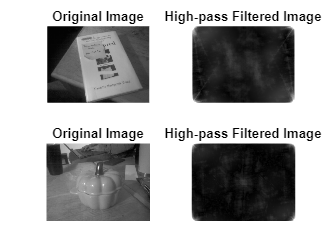

% Apply high pass filter
[~, highpass1] = high_pass_filter(image1,2);
[~, highpass2] = high_pass_filter(image2,2);

    
figure;
subplot(2,2,1)
imshow(image1)
title('Original Image')

subplot(2,2,2)
imshow(highpass1)
title('High-pass Filtered Image')

subplot(2,2,3)
imshow(image2)
title('Original Image')

subplot(2,2,4)
imshow(highpass2)
title('High-pass Filtered Image')

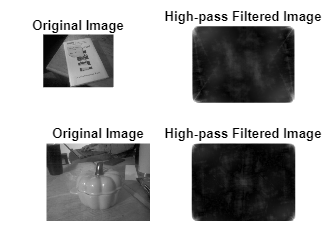

% Add noise, then filter images
ima = im2double(rgb2gray(imread('book.jpg')));
imb = im2double(rgb2gray(imread('pumpkin.jpg')));

% Apply gaussian and salt & pepper noises to each image
a_gauss = imnoise(ima,"gaussian");
a_sp = imnoise(ima,"salt & pepper");
b_gauss = imnoise(imb,"gaussian");
b_sp = imnoise(imb,"salt & pepper");

% Filter the salt & pepper noise with the median filter
a_med_filter = medfilt2(a_sp);
b_med_filter = medfilt2(b_sp);

% Filter the gaussian noise with the gaussian filter
a_gauss_filter = imgaussfilt(a_gauss);
b_gauss_filter = imgaussfilt(b_gauss);

% Filter with low-pass filter
[~,lowpass3] = low_pass_filter(a_gauss,5);
[~,lowpass4] = low_pass_filter(b_gauss,5);


% Filter with high-pass filter
[~,highpass3] = high_pass_filter(a_gauss,5);
[~,highpass4] = high_pass_filter(b_gauss,5);

figure(1)
subplot(2,3,1)
imshow(ima)
title('Original Image')

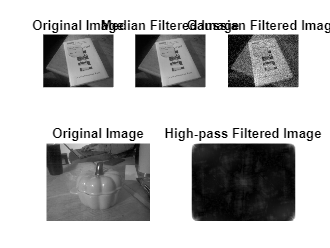


subplot(2,3,2)
imshow(a_med_filter)
title('Median Filtered Image')

subplot(2,3,3)
imshow(a_gauss_filter)
title('Gaussian Filtered Image')

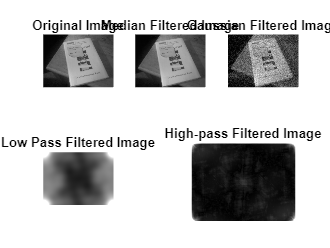


subplot(2,3,4)
imshow(lowpass3)
title('Low Pass Filtered Image')

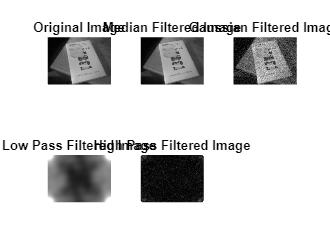


subplot(2,3,5)
imshow(highpass3)
title('High Pass Filtered Image')

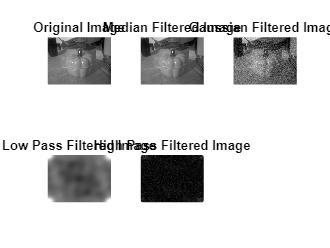

figure(2)
subplot(2,3,1)
imshow(imb)
title('Original Image')

subplot(2,3,2)
imshow(b_med_filter)
title('Median Filtered Image')

subplot(2,3,3)
imshow(b_gauss_filter)
title('Gaussian Filtered Image')

subplot(2,3,4)
imshow(lowpass4)
title('Low Pass Filtered Image')

subplot(2,3,5)
imshow(highpass4)
title('High Pass Filtered Image')